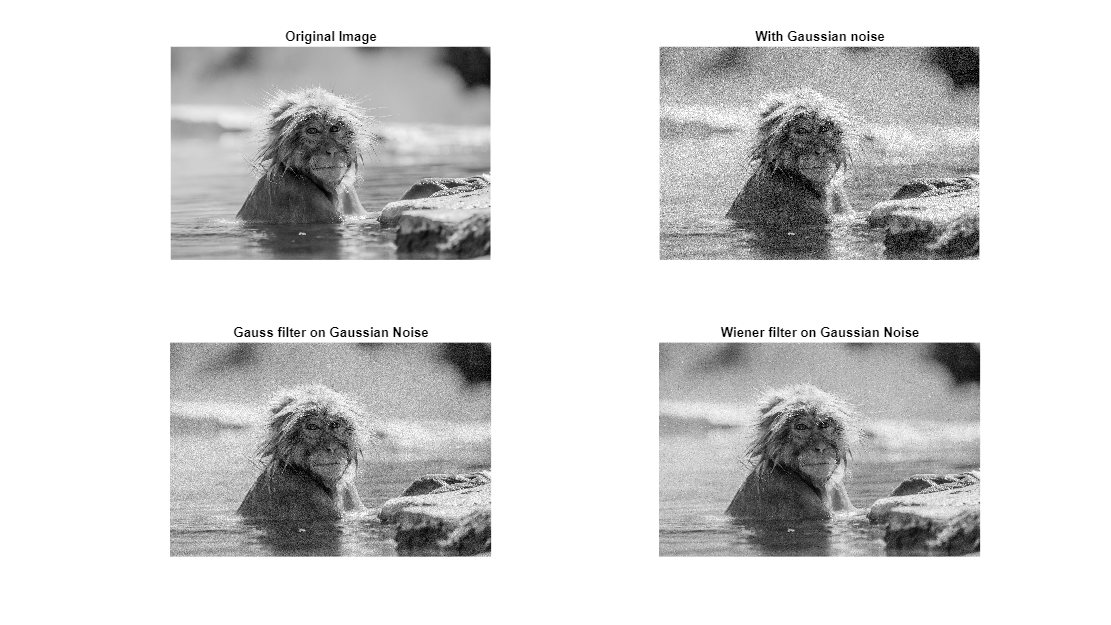

 
[fname, fpath] = uigetfile( ...
    {'*.jpg;*.jpeg;*.png'}, ...
    'Select file to open' ...
);

im = imread([fpath, fname]);
im = im2gray(im);

gaussNoisyIm = imnoise(im, 'gaussian');
poissNoisyIm = imnoise(im, 'poisson');
spNoisyIm = imnoise(im, 'salt & pepper');
speckNoisyIm = imnoise(im, 'speckle');

gaussFilterGaussIm = imgaussfilt(gaussNoisyIm);
gaussFilterPoissIm = imgaussfilt(poissNoisyIm);

meanFilterIm = filter2(fspecial('average', 3), poissNoisyIm) / 255;

medianFilterIm = medfilt2(spNoisyIm);

wienerFilterGaussIm = wiener2(gaussNoisyIm);
wienerFilterPoissIm = wiener2(poissNoisyIm);
wienerFilterSpIm = wiener2(spNoisyIm);
wienerFilterSpeckIm = wiener2(speckNoisyIm);

f1 = figure(Name="Image smoothening - Gaussian Noise");
f1.Position = [0 0 1920 1080];
axis off;
subplot(2, 2, 1);
imshow(im);
title("Original Image");
subplot(2, 2, 2);
imshow(gaussNoisyIm);
title("With Gaussian noise");
subplot(2, 2, 3);
imshow(gaussFilterGaussIm);
title("Gauss filter on Gaussian Noise");
subplot(2, 2, 4);
imshow(wienerFilterGaussIm);
title("Wiener filter on Gaussian Noise");

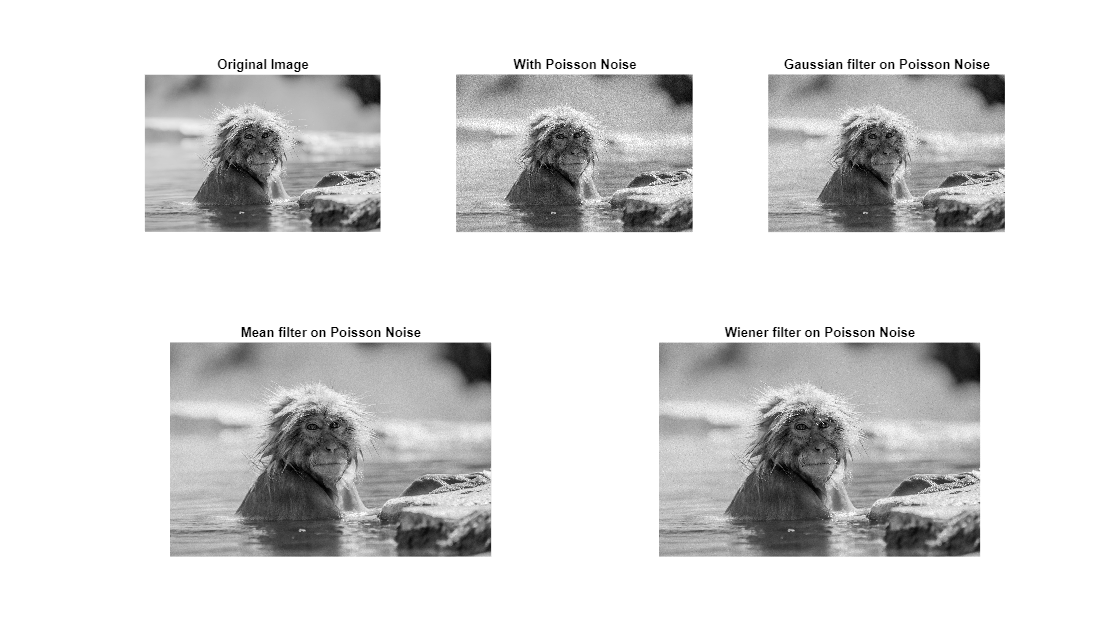

f2 = figure(Name="Image smoothening - Poisson Noise");
f2.Position = [0 0 1920 1080];
axis off;
subplot(2, 3, 1);
imshow(im);
title("Original Image");
subplot(2, 3, 2);
imshow(poissNoisyIm);
title("With Poisson Noise");
subplot(2, 3, 3);
imshow(gaussFilterPoissIm);
title("Gaussian filter on Poisson Noise");
subplot(2, 2, 3);
imshow(meanFilterIm);
title("Mean filter on Poisson Noise");
subplot(2, 2, 4);
imshow(wienerFilterPoissIm);
title("Wiener filter on Poisson Noise");

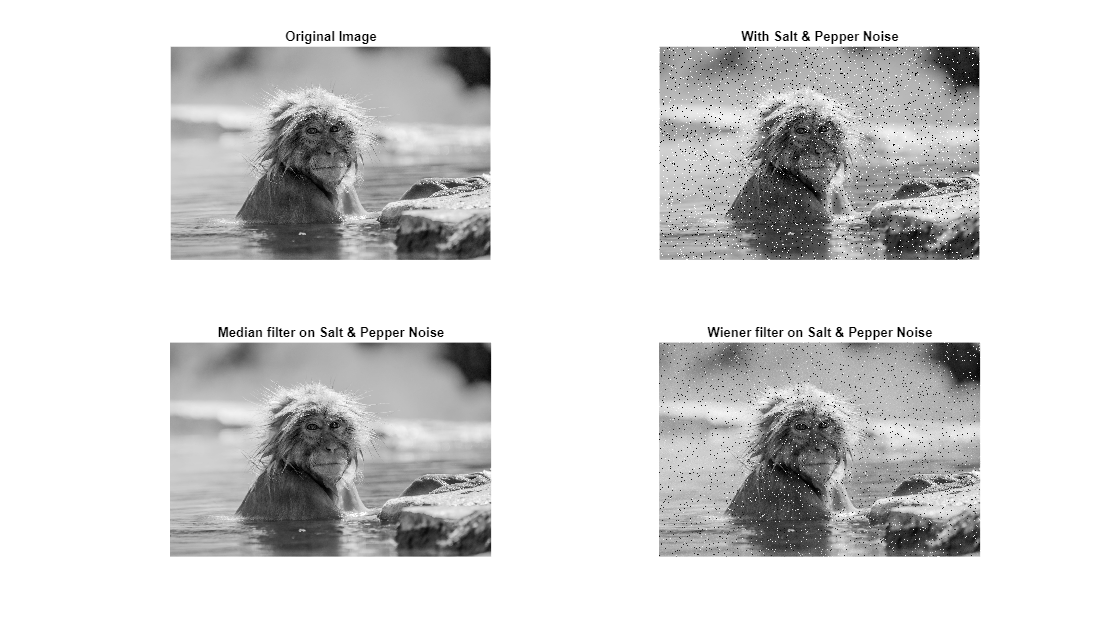

f3 = figure(Name="Image smoothening - Salt & Pepper Noise");
f3.Position = [0 0 1920 1080];
axis off;
subplot(2, 2, 1);
imshow(im);
title("Original Image");
subplot(2, 2, 2);
imshow(spNoisyIm);
title("With Salt & Pepper Noise");
subplot(2, 2, 3);
imshow(medianFilterIm);
title("Median filter on Salt & Pepper Noise");
subplot(2, 2, 4);
imshow(wienerFilterSpIm);
title("Wiener filter on Salt & Pepper Noise");

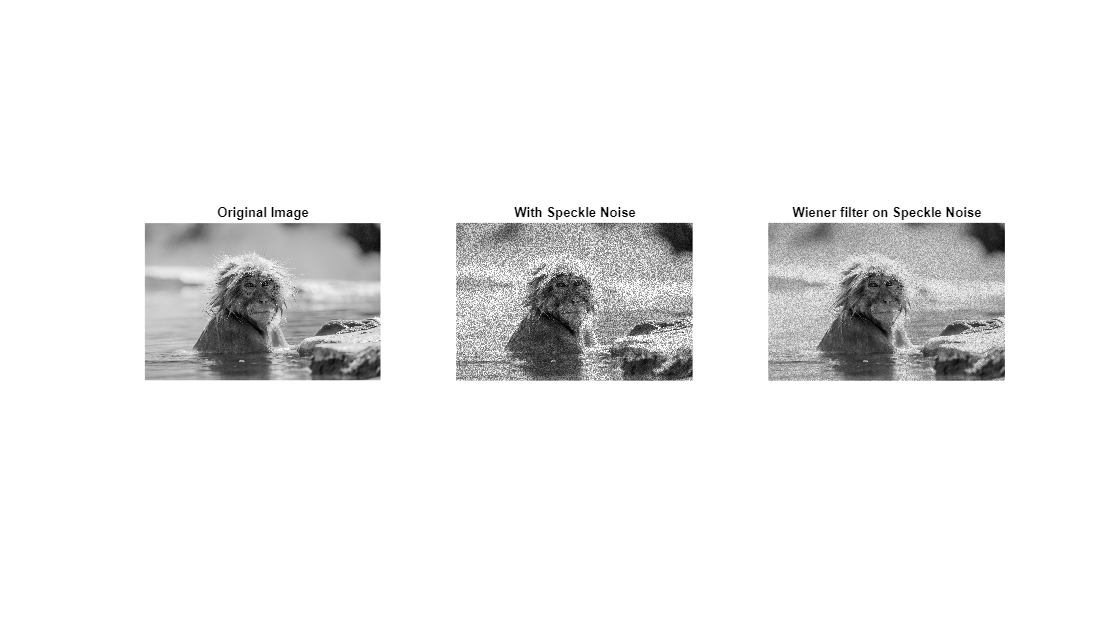

f4 = figure(Name="Image smoothening - Speckle Noise");
f4.Position = [0 0 1920 1080];
axis off;
subplot(1, 3, 1);
imshow(im);
title("Original Image");
subplot(1, 3, 2);
imshow(speckNoisyIm)
title("With Speckle Noise");
subplot(1, 3, 3);
imshow(wienerFilterSpeckIm);
title("Wiener filter on Speckle Noise");